# Determine Is from fit of the V(I)

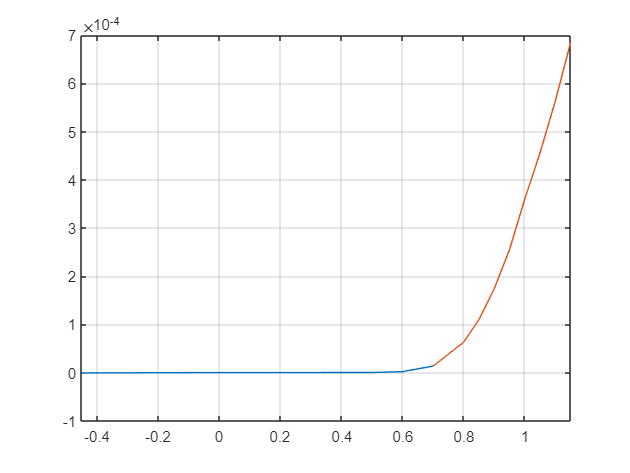

clearvars; close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\04_IV_curve_n2_max_b1.txt';
dummyStr = strsplit(LPath, '.');
SPath = [dummyStr{1}, '.mat'];
clear dummyStr

conv = 20e3; %Ohm

if endsWith(LPath, '.lvm')  % Dataset recorded in UTZ
    ivdata = importdata(LPath, '\t', 22);
    V = ivdata.data(:,2);
    I = ivdata.data(:,3);   %- 1e-7;
elseif endsWith(LPath, '.txt')  % Dataset recorded at SuSi building 12.8
    ivdata = importdata(LPath, '\t', 1);
    Vraw = ivdata.data(:,1);
    Iraw = ivdata.data(:,2)/conv;   
end
Iraw(2) = 0;
% Iraw(3) = Iraw(4);
% Iraw(4) = 0.5e-7;
start = 5;
V = Vraw(start:end);
I = Iraw(start:end);

% Plot
figure()
plot(Vraw, Iraw, V, I)
xlim([min(Vraw) max(Vraw)])
grid()

N_DIODE_IDEALITY = 1.9885;
nIs = 10;
Iss = linspace(150, 300, nIs);
Rs0 = 350;
alpha0 = 16.4;
T0 = 300/(alpha0*0.02585*N_DIODE_IDEALITY) - 273; % 83 Celsius
Vmodel = @(I, C) C(1)*I + 1/C(2)*log(I/(C(3)*1e-12) + 1);
[Rs, alpha, Is] = deal(zeros(nIs, 1));
Is0 = 150;
p0 = [Rs0, alpha0, Is0];
Vary = [200, 3, 150];
Fit = esfit(V, @(p) Vmodel(I, p), p0, Vary);

-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(p)Vmodel(I,p)
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
iteration   1: value 1.46505e-02   edge 1.00000e-01   initial simplex
iteration   2: value 9.65863e-03   edge 6.66667e+01   expansion
iteration   3: value 9.65863e-03   edge 6.66667e+01   reflection
iteration   4: value 8.72531e-03   edge 7.40741e+01   reflection
iteration   5: value 8.72531e-03   edge 2.96296e+01   contraction outside
iteration   6: value 8.72531e-03   edge 2.36626e+01   contraction inside
iteration   7: value 8.63930e-03   edge 2.81912e+01   reflection
iteration   8: value 8.58372e-03   edge 3.80684e+01   reflection
iteration   9: value 8.47102e-03   edge 2.74735e+01   contraction ou

Fit = repmat({Fit}, nIs, 1);
parfor iIs = 1:nIs
    % Is0 = 1e-12;
    Is0 = Iss(iIs);
    Fit{iIs} = esfit(V, @(p) Vmodel(I, p), [Rs0, alpha0, Is0], Vary);
end

-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(p)Vmodel(I,p)
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
iteration   1: value 2.23057e-02   edge 1.00000e-01   initial simplex
iteration   2: value 1.50220e-02   edge 6.66667e+01   expansion
iteration   3: value 1.50220e-02   edge 6.66667e+01   reflection
iteration   4: value 1.15649e-02   edge 9.87654e+01   expansion
iteration   5: value 1.15649e-02   edge 5.43210e+01   reflection
iteration   6: value 1.15649e-02   edge 6.03567e+01   reflection
iteration   7: value 1.15649e-02   edge 6.03567e+01   contraction inside
iteration   8: value 1.15649e-02   edge 4.11523e+01   contraction outside
iteration   9: value 1.15649e-02   edge 2.97233e+01   contraction ins

    % T0 = 300/(alpha0*0.02585*2);
    % C(1) = Rs, C(2) = 1/alpha, C(3) = 1/Is
%     
%     II = linspace(I(1), 7e-4, 10000);
%     figure()
%     plot(V, I, 'o')
%     hold on
%     plot(Vmodel(II, p0), II)

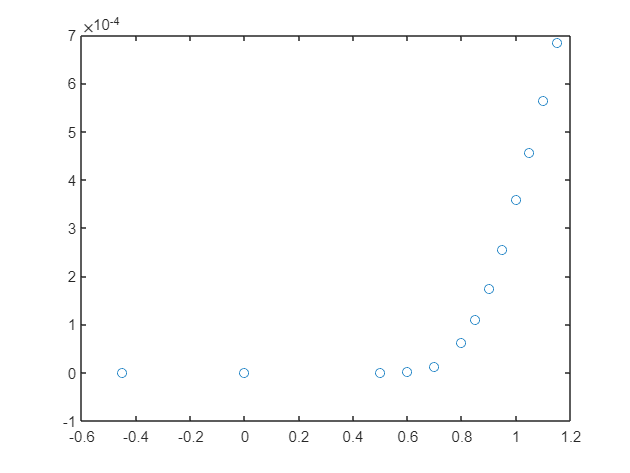

Undefined variable 'Fit'.

    % esfit(V, @(p) Vmodel(I, p), p0, p0);

% Rs = Fit.pfit(1); alpha = Fit.pfit(2); Is = 1e-12*Fit.pfit(3);
% dRs = Fit.pstd(1); dalpha = Fit.pstd(2); dIs = 1e-12*Fit.pstd(3);
% T = 300/(alpha*0.02585*N_DIODE_IDEALITY) - 273; dT = 77;
% mssg = [
%     sprintf('Rs = %f +- %f\n', Rs, dRs), ...
%     sprintf('alpha = %f +- %f, T = %f +- %f\n', alpha, dalpha, T, dn), ...
%     sprintf('Is = %e +- %e\n', Is, dIs)
%     ];
% disp(mssg)
II = linspace(0, 7e-4, 10000);
for iFit = 1:nIs
    figure()
    plot(Vraw, Iraw, 'o')
    hold on
    plot(Vmodel(II, Fit{iFit}.pfit), II)
    Fit{iFit}.rmsd*1e10 - 1.71475772932e7
end

## Divide logarithmic and linear part of the fit

% IsInv0 = p0(3);
% OptFit = optimset('display', 'off');
% IsInv = lsqnonlin(@(p) V - lmdivideLog(tF, zF(:, i), p), ...
%      IsInv0, [],[], OptFit);

%% Linear/non-linear fitting model

function [yfit, amplitude] = lmdivideLog(x, y, tau)
% First calculate the exponential without scaling, then fit the linear
% scaling parameter.
yfit = exp(-x/tau);
amplitude = yfit(:) \ y(:); % Solve linear equation: yfit * amplitude = y.
yfit = yfit * amplitude;
end